clc; 
clear;
syms a c h x

OIF =2

OIF = 2

% OIF Order of Interpolation Function foe element
% No of elements
e = 4;
% No of Nodal points
n =e+1;

f = 4*x^2 - 2*x -4; % Source term

exact_sol_f = -2*x^2+x;

% numerical values for a, c, and h
a_num = 1;
c_num = -2;
% domain of X
x0 = 0;
xn = 1;
% Element length
h_num = (xn - x0) / e;


[phi_e,nLP,Difference] = ShapeFunctions(OIF) % Gives shape functions and No of Nodal points for element

$$phi\_e = \left(\begin{array}{ccc} \frac{2\,\left(h-x\right)\,\left(\frac{h}{2}-x\right)}{h^{2}} & \frac{4\,x\,\left(h-x\right)}{h^{2}} & -\frac{2\,x\,\left(\frac{h}{2}-x\right)}{h^{2}} \end{array}\right)$$

nLP = 3

$$Difference = \frac{h}{2}$$


Difference = subs(Difference,h,h_num) 

$$Difference = \frac{1}{8}$$


% At nodel point the value of x
X = (x0:Difference:xn)';

% Local stiffness matrix
KNM_local = zeros(nLP, nLP, 'sym');
CNM_local = zeros(nLP, nLP, 'sym');

for N = 1:nLP
    for M = 1:nLP
        % Integrate to get the local stiffness matrix
        KNM_local(N, M) = int(a * diff(phi_e(N), x) * diff(phi_e(M), x) - c * phi_e(N) * phi_e(M), x, 0, h);
        CNM_local(N, M) = int(-1* phi_e(N) * phi_e(M), x, 0, h);
    end
end

% Display the local stiffness matrix
disp('Local Stiffness Matrix some element e:');

Local Stiffness Matrix some element e:


disp(KNM_local);

$$\begin{array}{l} \left(\begin{array}{ccc} \frac{7\,a}{3\,h}-\frac{2\,c\,h}{15} & \sigma_{1} & \frac{c\,h}{30}+\frac{a}{3\,h}\\ \sigma_{1} & \frac{16\,a}{3\,h}-\frac{8\,c\,h}{15} & \sigma_{1}\\ \frac{c\,h}{30}+\frac{a}{3\,h} & \sigma_{1} & \frac{7\,a}{3\,h}-\frac{2\,c\,h}{15} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{c\,h}{15}-\frac{8\,a}{3\,h} \end{array}$$

disp('Local C_NM Matrix some element e:');

Local C_NM Matrix some element e:


disp(CNM_local);

$$\left(\begin{array}{ccc} -\frac{2\,h}{15} & -\frac{h}{15} & \frac{h}{30}\\ -\frac{h}{15} & -\frac{8\,h}{15} & -\frac{h}{15}\\ \frac{h}{30} & -\frac{h}{15} & -\frac{2\,h}{15} \end{array}\right)$$



% Substitute values into the local  matrices
KNM_local_sub = subs(KNM_local, {a, c, h}, {a_num, c_num, h_num});
CNM_local_sub = subs(CNM_local, h, h_num);

% Display the substituted local stiffness matrix
disp('Substituted values of a c and h in Local Stiffness Matrix:');

Substituted values of a c and h in Local Stiffness Matrix:


disp(KNM_local_sub);

$$\left(\begin{array}{ccc} \frac{47}{5} & -\frac{319}{30} & \frac{79}{60}\\ -\frac{319}{30} & \frac{108}{5} & -\frac{319}{30}\\ \frac{79}{60} & -\frac{319}{30} & \frac{47}{5} \end{array}\right)$$

disp('Substituted value h in Local C_NM Matrix:');

Substituted value h in Local C_NM Matrix:


disp(CNM_local_sub);

$$\left(\begin{array}{ccc} -\frac{1}{30} & -\frac{1}{60} & \frac{1}{120}\\ -\frac{1}{60} & -\frac{2}{15} & -\frac{1}{60}\\ \frac{1}{120} & -\frac{1}{60} & -\frac{1}{30} \end{array}\right)$$

%generl formula for finding size of gloabl stiffness matrix-(S=OIF*e+1
S=OIF*e+1;
global_matrix_size = S; % each element has 2 nodal points
% Initialize global stiffness matrix


K_global = zeros(global_matrix_size);
C_global = zeros(global_matrix_size);

% Loop through each element
for element = 1:nLP-1:S-1

    % Assemble local stiffness matrix into global stiffness matrix
    start_index = element;
    end_index = element + nLP-1;
    K_global(start_index:end_index, start_index:end_index) = K_global(start_index:end_index, start_index:end_index) + KNM_local_sub;
    C_global(start_index:end_index, start_index:end_index) = C_global(start_index:end_index, start_index:end_index) + CNM_local_sub;
end

% Display global stiffness matrix
disp('Global Stiffness Matrix:')

Global Stiffness Matrix:


disp(K_global);

    9.4000  -10.6333    1.3167         0         0         0         0         0         0
  -10.6333   21.6000  -10.6333         0         0         0         0         0         0
    1.3167  -10.6333   18.8000  -10.6333    1.3167         0         0         0         0
         0         0  -10.6333   21.6000  -10.6333         0         0         0         0
         0         0    1.3167  -10.6333   18.8000  -10.6333    1.3167         0         0
         0         0         0         0  -10.6333   21.6000  -10.6333         0         0
         0         0         0         0    1.3167  -10.6333   18.8000  -10.6333    1.3167
         0         0         0         0         0         0  -10.6333   21.6000  -10.6333
         0         0         0         0         0         0    1.3167  -10.6333    9.4000



disp('Global C Matrix:')

Global C Matrix:


disp(C_global);

   -0.0333   -0.0167    0.0083         0         0         0         0         0         0
   -0.0167   -0.1333   -0.0167         0         0         0         0         0         0
    0.0083   -0.0167   -0.0667   -0.0167    0.0083         0         0         0         0
         0         0   -0.0167   -0.1333   -0.0167         0         0         0         0
         0         0    0.0083   -0.0167   -0.0667   -0.0167    0.0083         0         0
         0         0         0         0   -0.0167   -0.1333   -0.0167         0         0
         0         0         0         0    0.0083   -0.0167   -0.0667   -0.0167    0.0083
         0         0         0         0         0         0   -0.0167   -0.1333   -0.0167
         0         0         0         0         0         0    0.0083   -0.0167   -0.0333



% Source vector Initialization 
f_x = sym(zeros(n, 1));
% Calculate f(x) for each x value symbolically and store in the vector
for i = 1:S
    f_x(i) = subs(f, x, X(i));
end
%disp(f_x);

%K_global_inverse=InverseTDMA(K_global)

CNM = C_global*f_x;

du_dx = -3;



% Dirichlet Boundary Conditions

K_global_D_bc = K_global;
g_x_D_bc = sym(zeros(S, 1));
GNM_D_bc= a_num*g_x_D_bc*du_dx;
RHS_D_bc = GNM_D_bc+CNM;

% Boundary Conditions1
u0 = 0;
K_global_D_bc(1,:)= [1,zeros(1, S-1)];  %u0 = 0
RHS_D_bc(1) = u0;  % RHS of equation

% Boundary Conditions2
un = -1;
K_global_D_bc(end,:)= [zeros(1, S-1), 1]  %un=-1

K_global_D_bc =     1.0000         0         0         0         0         0         0         0         0
  -10.6333   21.6000  -10.6333         0         0         0         0         0         0
    1.3167  -10.6333   18.8000  -10.6333    1.3167         0         0         0         0
         0         0  -10.6333   21.6000  -10.6333         0         0         0         0
         0         0    1.3167  -10.6333   18.8000  -10.6333    1.3167         0         0
         0         0         0         0  -10.6333   21.6000  -10.6333         0         0
         0         0         0         0    1.3167  -10.6333   18.8000  -10.6333    1.3167
         0         0         0         0         0         0  -10.6333   21.6000  -10.6333
         0         0         0         0         0         0         0         0    1.0000


RHS_D_bc(end) = un;  % RHS of equation

% % for finding inverse I'm using My TDMA inverse function
% K_global_D_bc_inverse=InverseTDMA(K_global_D_bc);

% for finding inverse I'm using My TDMA inverse function
K_global_D_bc_inverse=inv(K_global_D_bc);

%The Solution of Dirichlet B.C. using FEM is =
u_D_bc = double(K_global_D_bc_inverse*RHS_D_bc);% u at nodal points
disp("-------------------------------------------------------------")

-------------------------------------------------------------


disp("The Solution of Dirichlet B.C. using FEM is")

The Solution of Dirichlet B.C. using FEM is


myTable = table(X, u_D_bc, 'VariableNames', {'Nodal point', 'u'});
disp(myTable);

    Nodal point        u     
    ___________    __________

        0          8.6343e-16
        1/8           0.09375
        1/4             0.125
        3/8           0.09375
        1/2        -5.266e-16
        5/8          -0.15625
        3/4            -0.375
        7/8          -0.65625
        1                  -1



disp("-------------------------------------------------------------")

-------------------------------------------------------------


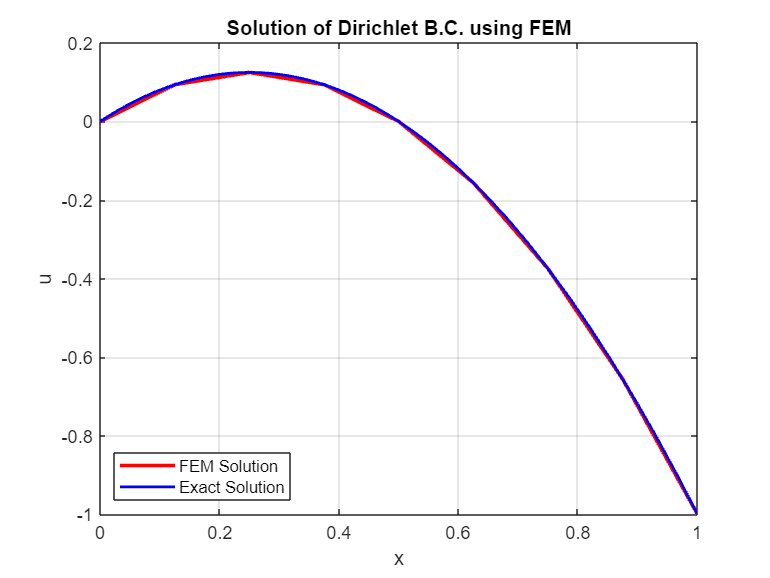

%Plot the FDM Solution and the actual solution
figure;
plot(X, u_D_bc, "r", "LineWidth", 2, "DisplayName", "FEM Solution"); 
hold on;
fplot(x, exact_sol_f, [0 1], "b", "LineWidth", 1.5, "DisplayName", "Exact Solution");
xlabel("x");
ylabel("u");
title("Solution of Dirichlet B.C. using FEM");
legend('Location', 'southwest');
grid on;


du_dx = -3; % at end point x = 1

% Neumann boundary Conditions
K_global_n_bc = K_global;
g_x_n_bc = sym(zeros(S, 1));
g_x_n_bc(end)=1;

GNM_n_bc= a_num*g_x_n_bc*du_dx;
RHS_n_bc = GNM_n_bc+CNM;

% Boundary Conditions1
u0 = 0;
K_global_n_bc(1,:)= [1,zeros(1, S-1)];  %u0 = 0
RHS_n_bc(1) = u0;  % RHS of equation


% % for finding inverse I'm using My TDMA inverse function
% K_global_n_bc_inverse=InverseTDMA(K_global_n_bc);
% for finding inverse I'm using My TDMA inverse function
K_global_n_bc_inverse=inv(K_global_n_bc);

%The Solution of Dirichlet B.C. using FEM is =
u_n_bc = double(K_global_n_bc_inverse*RHS_n_bc);% u at nodal points
disp("-------------------------------------------------------------")

-------------------------------------------------------------


disp("The Solution of Neumann B.C. using FEM with Phantom Node is");

The Solution of Neumann B.C. using FEM with Phantom Node is


Table2 = table(X, u_n_bc, 'VariableNames', {'Nodal point', 'u'});
disp(Table2);

    Nodal point        u     
    ___________    __________

        0          8.6343e-16
        1/8           0.09375
        1/4             0.125
        3/8           0.09375
        1/2        3.7765e-16
        5/8          -0.15625
        3/4            -0.375
        7/8          -0.65625
        1                  -1



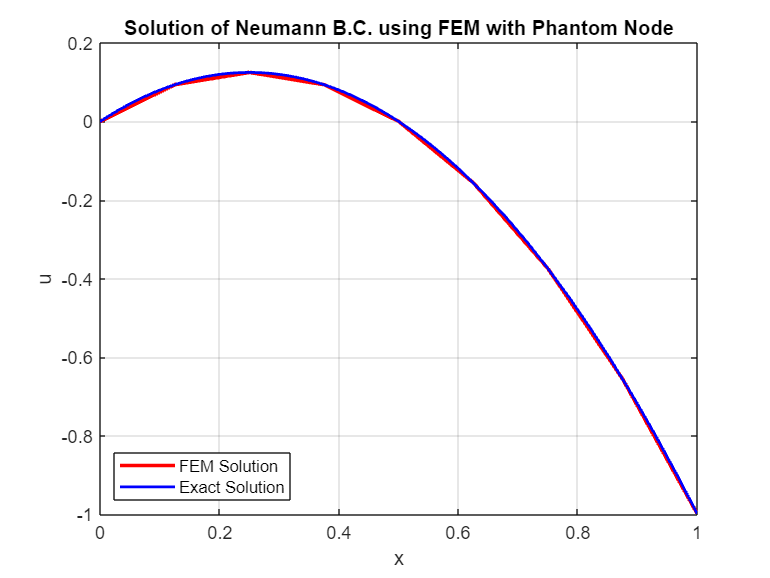


%Plot the FDM Solution and the actual solution
figure;
plot(X, u_n_bc, "r", "LineWidth", 2, "DisplayName", "FEM Solution"); 
hold on;
fplot(x, exact_sol_f, [0 1], "b", "LineWidth", 1.5, "DisplayName", "Exact Solution");
xlabel("x");
ylabel("u");
title("Solution of Neumann B.C. using FEM with Phantom Node");
legend('Location', 'southwest');
grid on;

function [X] = InverseTDMA(T)
    [n, ~] = size(T);

    % Check if T is tridiagonal
    for a = 1:n
        for b = 1:n
            if a ~= b && a ~= b - 1 && a ~= b + 1 && T(a, b) ~= 0
                disp('The given matrix is not a tridiagonal matrix');
                %n = 0;
                return;
            end
        end
    end

    B = eye(n); % Initialize B as an identity matrix

    % Decompose T using row operations
    for i = 2:n
        T(i, i - 1) = T(i, i - 1) / T(i - 1, i - 1);
        T(i, i) = T(i, i) - T(i, i - 1) * T(i - 1, i);
    end

    % Perform row operations on B
    for j = 1:n
        for i = 2:n
            B(i, j) = B(i, j) - T(i, i - 1) * B(i - 1, j);
        end
    end

    X = zeros(n, n); % Initialize X as a zero matrix

    % Back substitution to find the inverse matrix X
    for p = 1:n
        X(n, p) = B(n, p) / T(n, n); % Find the last element of each column
        for q = n - 1:-1:1
            X(q, p) = (B(q, p) - T(q, q + 1) * X(q + 1, p)) / T(q, q); % Compute elements in reverse order
        end
    end

    %disp('The inverse for the given matrix Tridigonal matrix, computed using the TDMA, is:');
end

function [N_sub,n,Differe] = ShapeFunctions(OIF)  % Gives shape functions and No of Nodal points for element
    syms x h;
    % OIF Order of Interpolation Function foe element
    % No of sub elements in element
    e = OIF;
    % No of Nodal points in element
    n =e+1; 
    
    x_local = sym(zeros(1, n)); % Initialize vector with zeros
    % Local Nodel points for element
    Differe = 0;
    for i = 1:n
        x_local(i) = (i-1)*h/e; % Calculate the elements of the vector
        if i ==2
        Differe = (i-1)*h/e;
        end
    end
    
    %disp(x_local); % Display the vector
    
    x_string = sym('x', [1 n]);
    
    N = sym(zeros(size(x_string)));
    
    % Generating Lagrange interpolating polynomial
    for j = 1:n
        % Compute the product term for each j
        product_term = 1;
        for k = 1:n
            if k ~= j
                product_term = product_term * (x - x_string(k)) / (x_string(j) - x_string(k));
            end
        end
    
        N(j)=product_term;
    end
    
    N_sub = subs(N,x_string,x_local);
end

